## Multiple FFT Testing

Testing out a program to decompose multiple FFTs into smaller 


Z = fft_decomposition(accZ(1, 1:5120), 1024)

The largest error amplitude is 3.35162e-14


Z = 	1.0e+02 *

  -0.0198 + 0.0000i   0.0173 - 0.0096i  -0.0169 + 0.0252i  -0.0111 + 0.0098i  -0.0051 + 0.0331i  -0.0033 - 0.0051i   0.0141 + 0.0089i   0.0154 + 0.0245i  -0.0085 + 0.0196i  -0.0139 + 0.0201i  -0.0190 + 0.0292i   0.0013 + 0.0128i  -0.0229 + 0.0302i  -0.0167 + 0.0356i  -0.0141 + 0.0397i  -0.0188 + 0.0424i  -0.0095 + 0.0495i  -0.0082 + 0.0658i  -0.0099 + 0.0568i  -0.0502 + 0.0638i  -0.0204 + 0.1080i  -0.0468 + 0.1271i  -0.0514 + 0.1570i  -0.0604 + 0.2492i  -0.0434 + 0.4096i  -0.1213 + 1.0236i   0.3092 - 1.7938i   0.0806 - 0.5312i   0.0416 - 0.3190i   0.0139 - 0.2115i   0.0084 - 0.1463i   0.0126 - 0.1450i   0.0058 - 0.1117i  -0.0001 - 0.0967i   0.0222 - 0.0677i   0.0372 - 0.0876i   0.0052 - 0.0812i   0.0120 - 0.0756i  -0.0129 - 0.0753i  -0.0126 - 0.0507i   0.0261 - 0.0767i   0.0126 - 0.0630i  -0.0114 - 0.0499i  -0.0007 - 0.0472i  -0.0184 - 0.0429i   0.0106 - 0.0436i  -0.0124 - 0.0393i   0.0125 - 0.0800i   0.0001 - 0.0717i  -0.0094 - 0.0730i


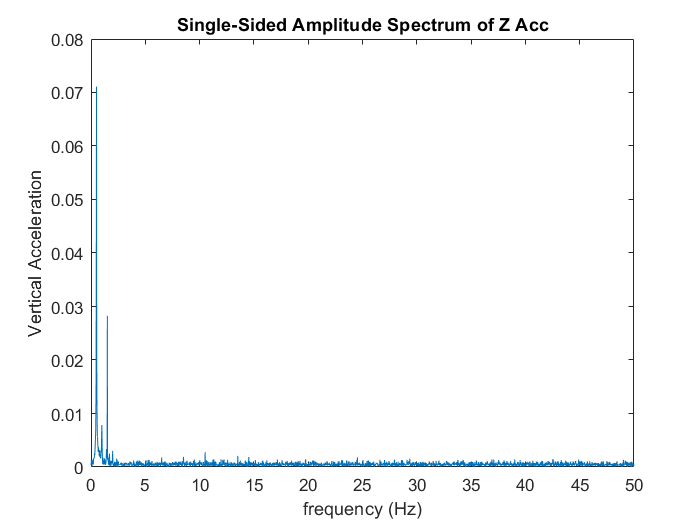

L = length(Z);
P2 = abs(Z/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
fs = 100;
f = fs*(0:(L/2))/L;


plot(f, abs(P1)) 
title('Single-Sided Amplitude Spectrum of Z Acc')
xlabel('frequency (Hz)')
ylabel('Vertical Acceleration')

function y = fft_decomposition(x, M)
% y = fft_decomposition(x, M)
% Computes FFT by decomposing into smaller FFTs.
%
% Inputs:
% x is a 1D array of the input data.
% M is the size of one of the FFTs to use.
%
% Outputs:
% y is the FFT of x.  It has been computed using FFTs of size M and
% length(x)/M.
%
% Note that this implementation doesn't explicitly use the 2D array U; it
% works on samples of x in-place.

q = 1;   % Offset because MATLAB starts at one.  Set to 0 for C code.
x_original = x;
P = length(x);
if mod(P,M)~=0, error('Invalid block size.'); end;
N = P/M;

% step 2: FFT-N on rows of U.
for m = 0 : M-1
    x(q+(m:M:P-1)) = fft(x(q+(m:M:P-1)));
end;

% step 3: Twiddle factors.
for m = 0 : M-1
    for n = 0 : N-1
        x(m+n*M+q) = x(m+n*M+q) * exp(-2*pi*j*m*n/P);
    end;
end;

% step 4:  FFT-M on columns of U.
for n = 0 : N-1
    x(q+n*M+(0:M-1)) = fft(x(q+n*M+(0:M-1)));
end;

% step 5:  Re-arrange samples for output.
y = zeros(size(x));
for m = 0 : M-1
    for n = 0 : N-1
        y(m*N+n+q) = x(m+n*M+q);
    end;
end;

err = max(abs(y-fft(x_original)));
fprintf( 1, 'The largest error amplitude is %g\n', err);
return;
% End of fft_decomposition().

end